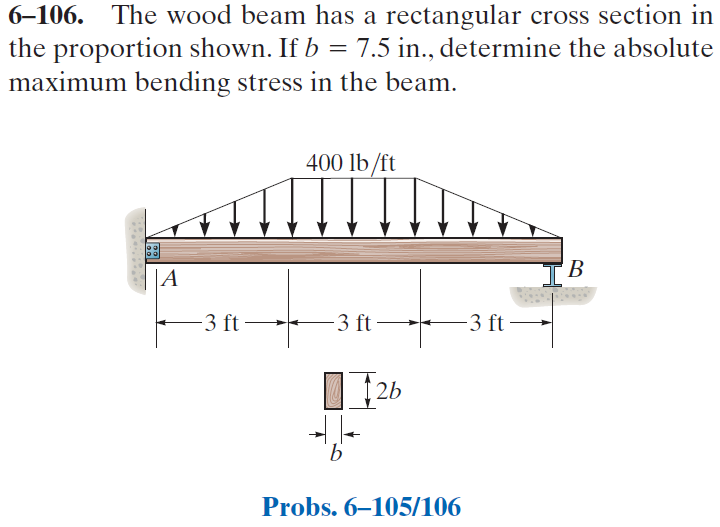

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-106P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-106P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1 = findpoly(1, 'thru', [0 0], 'thru', [3*u.ft -400*u.lbf/u.ft]);
w2(x) = -400*u.lbf/u.ft;
w3 = findpoly(1, 'thru', [6*u.ft -400*u.lbf/u.ft], 'thru', [9*u.ft 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 9*u.ft);
b = b.add('distributed', 'force', w1, [0 3]*u.ft);
b = b.add('distributed', 'force', w2, [3 6]*u.ft, [false true]);
b = b.add('distributed', 'force', w3, [6 9]*u.ft, [false true]);
b.L = 9*u.ft;

# section properties

B = 7.5*u.in;
H = 2*B;
b.I = rewrite(B*H^3/12, u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{4096\,x\,\left(x^{4}-180\,x^{2}\,{\mathrm{ft}}^{2}+8910\,{\mathrm{ft}}^{4}\right)}{375\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{6}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{4096\,\left(5\,x^{4}-90\,x^{3}\,\mathrm{ft}+90\,x^{2}\,{\mathrm{ft}}^{2}+2835\,x\,{\mathrm{ft}}^{3}+81\,{\mathrm{ft}}^{4}\right)}{125\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{5}} & \text{ if }x\in \left(3\,\mathrm{ft},6\,\mathrm{ft}\right]\\ \frac{4096\,\left(x-9\,\mathrm{ft}\right)\,\left(x^{4}-36\,x^{3}\,\mathrm{ft}+306\,x^{2}\,{\mathrm{ft}}^{2}+324\,x\,{\mathrm{ft}}^{3}+891\,{\mathrm{ft}}^{4}\right)}{375\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{6}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{4096\,\left(x^{4}-108\,x^{2}\,{\mathrm{ft}}^{2}+1782\,{\mathrm{ft}}^{4}\right)}{75\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{6}} & \text{ if }x\leq 3\,\mathrm{ft}\\ \frac{4096\,\left(2\,x-9\,\mathrm{ft}\right)\,\left(-2\,x^{2}+18\,x\,\mathrm{ft}+63\,{\mathrm{ft}}^{2}\right)}{25\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{5}} & \text{ if }x\in \left(3\,\mathrm{ft},6\,\mathrm{ft}\right]\\ -\frac{4096\,\left(-x^{4}+36\,x^{3}\,\mathrm{ft}-378\,x^{2}\,{\mathrm{ft}}^{2}+972\,x\,{\mathrm{ft}}^{3}+405\,{\mathrm{ft}}^{4}\right)}{75\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{6}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{200\,x\,\left(54\,{\mathrm{ft}}^{2}-x^{2}\right)}{9}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -200\,\left(x^{2}-9\,x\,\mathrm{ft}+3\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\in \left(3\,\mathrm{ft},6\,\mathrm{ft}\right]\\ \frac{200\,\left(x-9\,\mathrm{ft}\right)\,\left(x^{2}-18\,x\,\mathrm{ft}+27\,{\mathrm{ft}}^{2}\right)}{9}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{200\,\left(18\,{\mathrm{ft}}^{2}-x^{2}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -200\,\left(2\,x-9\,\mathrm{ft}\right)\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\in \left(3\,\mathrm{ft},6\,\mathrm{ft}\right]\\ \frac{200\,\left(x^{2}-18\,x\,\mathrm{ft}+63\,{\mathrm{ft}}^{2}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{400\,x}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -400\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\in \left(3\,\mathrm{ft},6\,\mathrm{ft}\right]\\ \frac{400\,\left(x-9\,\mathrm{ft}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 1200\,\mathrm{lbf}\\ \mathrm{Rb} & 1200\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

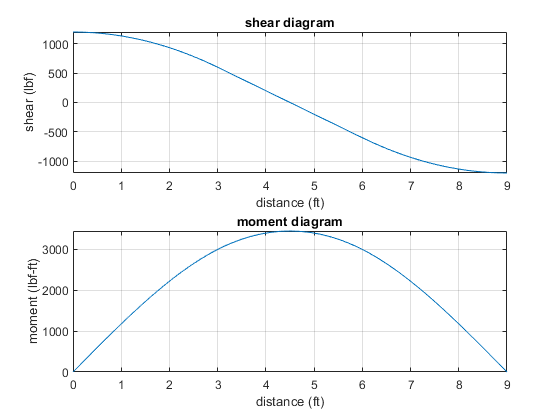

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# absolute maximum bending moment

assume(0 < x & x < b.L);
xmax = solve(v == 0);
M_max = m(xmax)

$$M\_max = 3450\,\mathrm{ft}\,\mathrm{lbf}$$

# absolute maximum bending stress

C = H/2;
b.I = rewrite(b.I, u.in);
sigma_max = rewrite(M_max*C/b.I, u.psi);
sigma_max_vpa = vpa(sigma_max) %#ok<NASGU> 

$$sigma\_max\_vpa = 147.2\,\mathrm{psi}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear sigma_max_vpa;